
g = @(x) (10.*sin(x).*exp(-x))-(3/2)

g = function_handle with value:
    @(x)(10.*sin(x).*exp(-x))-(3/2)


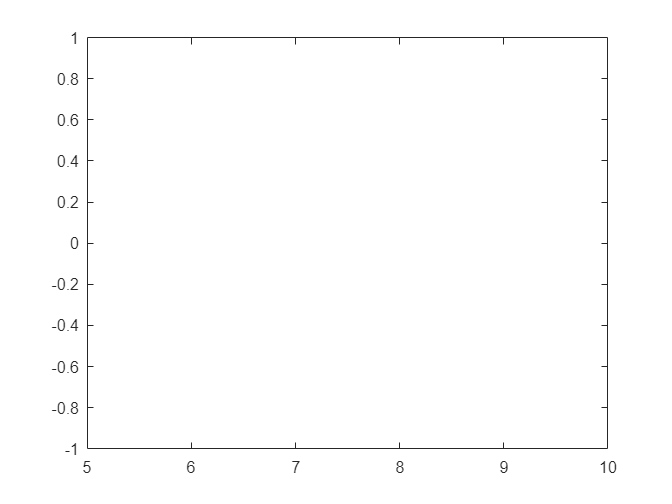


%fplot(g,[0 10])

ylim([-1 1])



root(1) = fzero(g,[1,10])

root =     1.8559    0.1807    1.0183


root(2) = fzero(g,[0,1])

root =     1.8559    0.1807    1.0183



root(3) = (root(1)+root(2))/2

root =     1.8559    0.1807    1.0183



f = @(x) x.^2 - 4 + sqrt((x+1))

f = function_handle with value:
    @(x)x.^2-4+sqrt((x+1))


fder =  @(x) 2*x +(x+1)^(-1/2)

fder = function_handle with value:
    @(x)2*x+(x+1)^(-1/2)




initialGuess = 1;

estRoots = zeros(7,1);
estRoots(1) = initialGuess;

for index = 1:3
    estRoots(index+1) = estRoots(index) - f(estRoots(index))/fder(estRoots(index));
end
clf
fun = @(x) -(sin(x+5)/(2*x) + 4 )

fun = function_handle with value:
    @(x)(sin(x+5)/(2*x)+4)



upfun

[x,fval] = fminbnd(fun,5,10)

x = 5.8256

fval = 3.9154


fplot(fun)

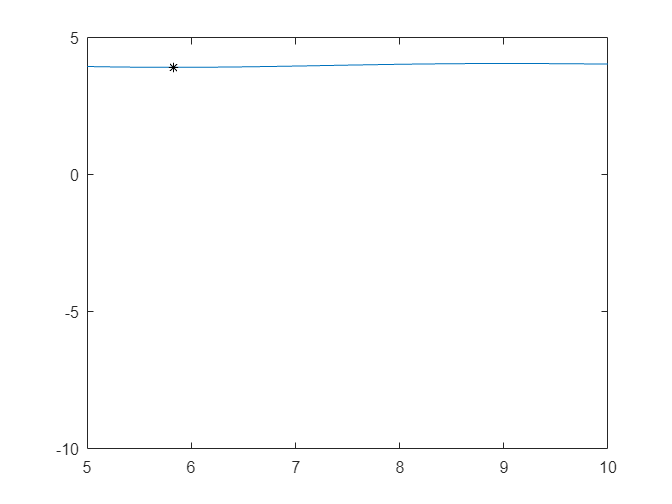


hold on;
plot(x,fval,'k*')
ylim([-10,5])
xlim([5,10])

function rootEstemate = NewtonIteration(funct,derFunct,initialGuess)

if nargin<3
    error('At least 3 input arguments required')
end

rootEstemate = initialGuess - funct(initialGuess)/derFunct(initialGuess);


end